clc;
clear;
close all;

%% ========================================================
% STEP 6: DRONE RIGID-BODY DYNAMICS
%
% INPUTS FROM PREVIOUS STEPS:
%
% Step 2:
%   t
%   dt
%   pd
%   vd
%   ad
%   waypoints
%
% Step 5:
%   desired_thrust
%   torque_command
%   R_desired_history
%
% OUTPUTS:
%   p_history
%   v_history
%   R_history
%   omega_history
%
% The controller is NOT calculated here.
% Step 6 only applies the control commands generated
% by Step 5 to the drone dynamics.
% ========================================================


%% --------------------------------------------------------
% 1. Load previous results
% ---------------------------------------------------------

load('drone_toy_model.mat');

numSamples = length(t);



%% --------------------------------------------------------
% 2. Check required variables
% ---------------------------------------------------------

requiredVariables = {
    't'
    'dt'
    'pd'
    'vd'
    'ad'
    'waypoints'
    'desired_thrust'
    'torque_command'
    'R_desired_history'
};

for i = 1:length(requiredVariables)

    if ~exist(requiredVariables{i},'var')

        error(['Missing variable: ', ...
               requiredVariables{i}, ...
               '. Run the previous step first.']);

    end

end


%% --------------------------------------------------------
% 3. Physical parameters
% ---------------------------------------------------------

% Drone mass

m = 1.0;                    % kg

% Gravity

g = [0; 0; -9.81];          % m/s^2

% Inertia matrix

J = diag([
    0.02;
    0.02;
    0.04
]);                         % kg m^2

% Body z-axis

e3 = [0; 0; 1];


%% --------------------------------------------------------
% 4. Initial actual drone state
% ---------------------------------------------------------

% Position

p = [0; 0; 0];

% Velocity

v = [0; 0; 0];

% Attitude

R = eye(3);

% Angular velocity

omega = [0; 0; 0];



%% --------------------------------------------------------
% 5. Storage
% ---------------------------------------------------------

p_history = ...
    zeros(numSamples,3);

v_history = ...
    zeros(numSamples,3);

R_history = ...
    zeros(3,3,numSamples);

omega_history = ...
    zeros(numSamples,3);

thrust_history = ...
    zeros(numSamples,1);

torque_history = ...
    zeros(numSamples,3);

position_error_history = ...
    zeros(numSamples,3);

velocity_error_history = ...
    zeros(numSamples,3);

attitude_error_history = ...
    zeros(numSamples,3);


%% ========================================================
% 6. Rigid-body dynamics loop
% ========================================================

for k = 1:numSamples


    %% ====================================================
    % A. Control input FROM STEP 5
    %
    % These are not recalculated here.
    %
    % T = desired thrust
    % tau = desired body torque
    % ====================================================

    T = ...
        desired_thrust(k);

    tau = ...
        torque_command(k,:)';


    %% ====================================================
    % B. Store current actual state
    %
    % These represent the physical drone state before
    % applying the control input at this time step.
    % ====================================================

    p_actual = p;

    v_actual = v;

    R_actual = R;

    omega_actual = omega;


    %% ====================================================
    % C. Thrust force in body frame
    %
    % F_body = [0; 0; T]
    % ====================================================

    F_body = ...
        T * e3;


    %% ====================================================
    % D. Convert thrust into world frame
    %
    % F_world = R F_body
    %
    % R maps body-frame vectors into world frame.
    % ====================================================

    F_world = ...
        R_actual * F_body;


    %% ====================================================
    % E. Translational dynamics
    %
    % Newton's second law:
    %
    % m * v_dot = m*g + F_world
    %
    % Therefore:
    %
    % v_dot = g + F_world/m
    % ====================================================

    p_dot = ...
        v_actual;

    v_dot = ...
        g + F_world/m;


    %% ====================================================
    % F. Rotational kinematics
    %
    % R_dot = R * skew(omega)
    % ====================================================

    R_dot = ...
        R_actual * skew(omega_actual);


    %% ====================================================
    % G. Rotational dynamics
    %
    % Euler rigid-body equation:
    %
    % J omega_dot =
    % tau - omega x (J omega)
    %
    % Therefore:
    %
    % omega_dot =
    % J^{-1}[tau - omega x (J omega)]
    % ====================================================

    omega_dot = ...
        J \ ...
        ( ...
        tau ...
        - cross( ...
            omega_actual, ...
            J*omega_actual) ...
        );


    %% ====================================================
    % H. Numerical integration
    %
    % Forward Euler for translational state
    % ====================================================

    p = ...
        p_actual + p_dot*dt;

    v = ...
        v_actual + v_dot*dt;

    omega = ...
        omega_actual + omega_dot*dt;


    %% ====================================================
    % I. Attitude integration on SO(3)
    %
    % R(k+1) =
    % R(k) Exp([omega(k)]x dt)
    %
    % This preserves the geometric rotation formulation.
    % ====================================================

    R = ...
        R_actual * ...
        expm( ...
            skew(omega_actual*dt) ...
        );


    %% ====================================================
    % J. Re-project numerical attitude onto SO(3)
    % ====================================================

    [U,~,V] = svd(R);

    R = U*V';

    if det(R) < 0

        U(:,3) = -U(:,3);

        R = U*V';

    end


    %% ====================================================
    % K. Store actual state
    % ====================================================

    p_history(k,:) = ...
        p_actual';

    v_history(k,:) = ...
        v_actual';

    R_history(:,:,k) = ...
        R_actual;

    omega_history(k,:) = ...
        omega_actual';


    %% ====================================================
    % L. Store control inputs
    % ====================================================

    thrust_history(k) = ...
        T;

    torque_history(k,:) = ...
        tau';


    %% ====================================================
    % M. Position tracking error
    %
    % This compares actual drone position against
    % the desired trajectory.
    % ====================================================

    position_error_history(k,:) = ...
        (pd(k,:)' - p_actual)';


    %% ====================================================
    % N. Velocity tracking error
    % ====================================================

    velocity_error_history(k,:) = ...
        (vd(k,:)' - v_actual)';


    %% ====================================================
    % O. Attitude tracking error
    %
    % e_R =
    % 1/2(R_d^T R - R^T R_d)^vee
    % ====================================================

    Rd = ...
        R_desired_history(:,:,k);

    E_R = ...
        0.5 * ...
        ( ...
        Rd'*R_actual ...
        - ...
        R_actual'*Rd ...
        );

    e_R = ...
        vee(E_R);

    attitude_error_history(k,:) = ...
        e_R';

end



%% ========================================================
% 7. Performance metrics
% ========================================================


%% Position RMSE

position_RMSE = ...
    sqrt( ...
        mean( ...
            position_error_history.^2, ...
            1));


%% Position error magnitude

position_error_norm = ...
    sqrt( ...
        sum( ...
            position_error_history.^2, ...
            2));


maximum_position_error = ...
    max(position_error_norm);


final_position_error = ...
    position_error_norm(end);


%% Velocity RMSE

velocity_RMSE = ...
    sqrt( ...
        mean( ...
            velocity_error_history.^2, ...
            1));


%% Attitude error magnitude

attitude_error_norm = ...
    sqrt( ...
        sum( ...
            attitude_error_history.^2, ...
            2));


attitude_RMSE = ...
    sqrt( ...
        mean( ...
            attitude_error_norm.^2));


%% ========================================================
% 8. Rotation matrix validity
% ========================================================

rotation_orthogonality_error = ...
    zeros(numSamples,1);

rotation_determinant_error = ...
    zeros(numSamples,1);


for k = 1:numSamples

    Rk = ...
        R_history(:,:,k);

    rotation_orthogonality_error(k) = ...
        norm( ...
            Rk'*Rk - eye(3), ...
            'fro');

    rotation_determinant_error(k) = ...
        abs(det(Rk)-1);

end


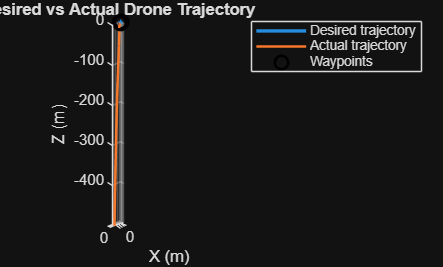


%% ========================================================
% 9. Plot desired vs actual 3D trajectory
% ========================================================

figure;

plot3( ...
    pd(:,1), ...
    pd(:,2), ...
    pd(:,3), ...
    'LineWidth',2);

hold on;

plot3( ...
    p_history(:,1), ...
    p_history(:,2), ...
    p_history(:,3), ...
    'LineWidth',1.5);

plot3( ...
    waypoints(:,1), ...
    waypoints(:,2), ...
    waypoints(:,3), ...
    'ko', ...
    'MarkerSize',8, ...
    'LineWidth',1.5);

grid on;

axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Desired vs Actual Drone Trajectory');

legend( ...
    'Desired trajectory', ...
    'Actual trajectory', ...
    'Waypoints');

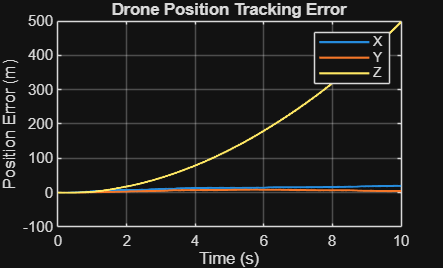


%% ========================================================
% 10. Position tracking error
% ========================================================

figure;

plot( ...
    t, ...
    position_error_history(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    position_error_history(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    position_error_history(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Position Error (m)');

title('Drone Position Tracking Error');

legend( ...
    'X', ...
    'Y', ...
    'Z');

grid on;

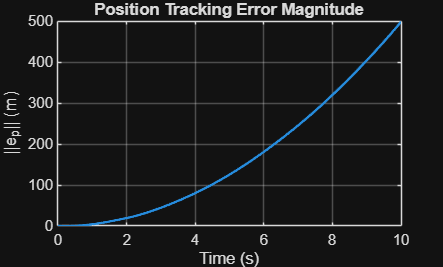


%% ========================================================
% 11. Position error magnitude
% ========================================================

figure;

plot( ...
    t, ...
    position_error_norm, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_p|| (m)');

title('Position Tracking Error Magnitude');

grid on;

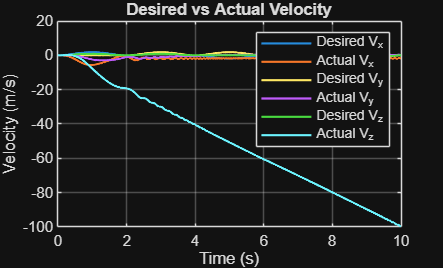



%% ========================================================
% 12. Desired vs actual velocity
% ========================================================

figure;

plot( ...
    t, ...
    vd(:,1), ...
    'LineWidth',1.3);

hold on;

plot( ...
    t, ...
    v_history(:,1), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    vd(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,2), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    vd(:,3), ...
    'LineWidth',1.3);

plot( ...
    t, ...
    v_history(:,3), ...
    'LineWidth',1.3);

xlabel('Time (s)');
ylabel('Velocity (m/s)');

title('Desired vs Actual Velocity');

legend( ...
    'Desired V_x', ...
    'Actual V_x', ...
    'Desired V_y', ...
    'Actual V_y', ...
    'Desired V_z', ...
    'Actual V_z');

grid on;

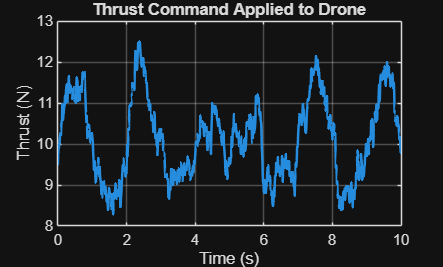



%% ========================================================
% 13. Thrust
% ========================================================

figure;

plot( ...
    t, ...
    thrust_history, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('Thrust (N)');

title('Thrust Command Applied to Drone');

grid on;

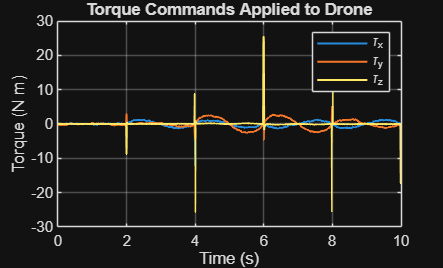



%% ========================================================
% 14. Torque
% ========================================================

figure;

plot( ...
    t, ...
    torque_history(:,1), ...
    'LineWidth',1.2);

hold on;

plot( ...
    t, ...
    torque_history(:,2), ...
    'LineWidth',1.2);

plot( ...
    t, ...
    torque_history(:,3), ...
    'LineWidth',1.2);

xlabel('Time (s)');
ylabel('Torque (N m)');

title('Torque Commands Applied to Drone');

legend( ...
    '\tau_x', ...
    '\tau_y', ...
    '\tau_z');

grid on;

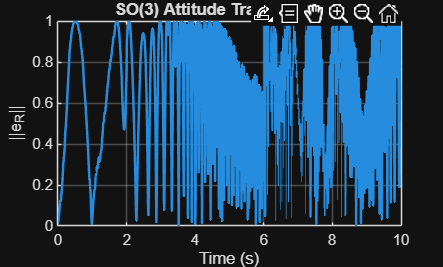



%% ========================================================
% 15. Attitude tracking error
% ========================================================

figure;

plot( ...
    t, ...
    attitude_error_norm, ...
    'LineWidth',1.5);

xlabel('Time (s)');
ylabel('||e_R||');

title('SO(3) Attitude Tracking Error');

grid on;


%% ========================================================
% 16. Display results
% ========================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('STEP 6 - DRONE DYNAMICS RESULTS\n');

STEP 6 - DRONE DYNAMICS RESULTS


fprintf('============================================\n');



fprintf('\nPosition RMSE:\n');


Position RMSE:



fprintf( ...
    'X = %.4f m\n', ...
    position_RMSE(1));

X = 13.3044 m



fprintf( ...
    'Y = %.4f m\n', ...
    position_RMSE(2));

Y = 5.9908 m



fprintf( ...
    'Z = %.4f m\n', ...
    position_RMSE(3));

Z = 222.9540 m




fprintf( ...
    '\nMaximum position error = %.4f m\n', ...
    maximum_position_error);


Maximum position error = 498.0934 m




fprintf( ...
    'Final position error = %.4f m\n', ...
    final_position_error);

Final position error = 498.0934 m




fprintf( ...
    '\nVelocity RMSE:\n');


Velocity RMSE:



fprintf( ...
    'X = %.4f m/s\n', ...
    velocity_RMSE(1));

X = 2.6342 m/s



fprintf( ...
    'Y = %.4f m/s\n', ...
    velocity_RMSE(2));

Y = 1.5689 m/s



fprintf( ...
    'Z = %.4f m/s\n', ...
    velocity_RMSE(3));

Z = 57.6265 m/s




fprintf( ...
    '\nAttitude RMSE = %.4f rad\n', ...
    attitude_RMSE);


Attitude RMSE = 0.7100 rad




fprintf( ...
    'Attitude RMSE = %.4f degrees\n', ...
    rad2deg(attitude_RMSE));

Attitude RMSE = 40.6823 degrees




fprintf( ...
    '\nMaximum thrust = %.4f N\n', ...
    max(thrust_history));


Maximum thrust = 12.4964 N




fprintf( ...
    'Average thrust = %.4f N\n', ...
    mean(thrust_history));

Average thrust = 10.1390 N




fprintf('\nMaximum torque:\n');


Maximum torque:



fprintf( ...
    'tau_x = %.4f N m\n', ...
    max(abs(torque_history(:,1))));

tau_x = 12.0304 N m



fprintf( ...
    'tau_y = %.4f N m\n', ...
    max(abs(torque_history(:,2))));

tau_y = 5.3519 N m



fprintf( ...
    'tau_z = %.4f N m\n', ...
    max(abs(torque_history(:,3))));

tau_z = 25.5643 N m




fprintf('\nSO(3) validity:\n');


SO(3) validity:



fprintf( ...
    'Maximum orthogonality error = %.4e\n', ...
    max(rotation_orthogonality_error));

Maximum orthogonality error = 1.6350e-15



fprintf( ...
    'Maximum determinant error = %.4e\n', ...
    max(rotation_determinant_error));

Maximum determinant error = 8.8818e-16




fprintf('\n============================================\n');



%% ========================================================
% 17. Save Step 6 results
% ========================================================

save( ...
    'drone_toy_model.mat', ...
    'waypoints', ...
    'waypointTime', ...
    't', ...
    'dt', ...
    'pd', ...
    'vd', ...
    'ad', ...
    'p_true', ...
    'v_true', ...
    'a_true', ...
    'R_true', ...
    'omega_true', ...
    'p_camera', ...
    'R_camera', ...
    'a_imu', ...
    'omega_imu', ...
    'p_est_history', ...
    'v_est_history', ...
    'R_est_history', ...
    'omega_est_history', ...
    'ba_est_history', ...
    'bg_est_history', ...
    'position_RMSE', ...
    'velocity_RMSE', ...
    'attitude_RMSE', ...
    'acceleration_command', ...
    'force_command', ...
    'desired_thrust', ...
    'R_desired_history', ...
    'attitude_error_history', ...
    'torque_command', ...
    'position_error_history', ...
    'velocity_error_history', ...
    'position_error_magnitude', ...
    'thrust_history', ...
    'torque_history', ...
    'p_history', ...
    'v_history', ...
    'R_history', ...
    'omega_history', ...
    'maximum_position_error', ...
    'final_position_error', ...
    'attitude_error_norm', ...
    'rotation_orthogonality_error', ...
    'rotation_determinant_error');


fprintf('\nStep 6 results saved to drone_toy_model.mat\n');


Step 6 results saved to drone_toy_model.mat




%% ========================================================
% LOCAL FUNCTIONS
% ========================================================

function S = skew(v)

    S = [
         0    -v(3)  v(2);
         v(3)  0    -v(1);
        -v(2) v(1)   0
    ];

end


function v = vee(S)

    v = [
        S(3,2);
        S(1,3);
        S(2,1)
    ];

end